# Discretización

## Ventanas

Diseñar 2 ventanas de N=1024 muestras con las funciones dedicadas. Plotearlas en tiempo y en frecuencia.

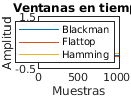

N=1024;
w_hamming=hamming(N);
w_flattop=flattopwin(N);
w_rect=rectwin(N);
w_blackman=blackman(N);
windows=table(w_blackman,w_flattop,w_hamming,'VariableNames',["Blackman" "Flattop" "Hamming"]);

%Plotear en tiempo
figure
plot(windows{:,:})
legend(windows.Properties.VariableNames)
ylim([-0.5 1.5])
xlabel("Muestras")
ylabel("Amplitud")
title("Ventanas en tiempo")

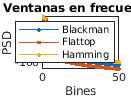


%Representación espectral
[Pxx,w]=periodogram(windows{:,:},[],N,[]);
windows_spectral=array2table(Pxx,"VariableNames",windows.Properties.VariableNames);

figure
plot(pow2db(windows_spectral{:,:}),'.-')
legend(windows.Properties.VariableNames)
xlabel("Bines")
ylabel("PSD")
title("Ventanas en frecuencia")
xlim([0 50])

Generar las siguientes formas de onda con 1024 muestras y guardar cada una en un campo de una tabla.

- 
$$x(t)=cos(4t)$$


- 
$$x(t)=cos(4t)+cos(4.5t)$$


- 
$$x(t)=cos(4t)+cos(8t)
$$


- 
$$x(t)=cos(4t)+0.001cos(8t)$$


Plotear tempralmente y en espacil de frecuencias

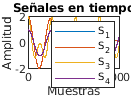

%Function handles
x_1= @(t) cos(4.*t);
x_2= @(t) cos(4.*t)+cos(4.5.*t);
x_3= @(t) cos(4.*t)+cos(8.*t);
x_4= @(t) cos(4.*t)+0.001.*cos(8.*t);
%Vector muestras
%t=(0:N-1)';
t=(linspace(0,6,N))';

%tabla de señales
signals=table(x_1(t),x_2(t),x_3(t),x_4(t),'VariableNames',["S_1" "S_2" "S_3" "S_4"]);

%Plotear en tiempo
figure
plot(signals{:,:})
legend(signals.Properties.VariableNames)
xlabel("Muestras")
ylabel("Amplitud")
title("Señales en tiempo")

Aplicar las ventanas a cada forma de onda mediante $y(t)=w(t)x(t)$ y alojarlas en distintas tablas

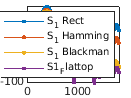

%Descomposicion espectral
%Con resolucion arbitrariamene grande
[Pxx,~]=periodogram(signals{:,:},[],100.*N,[]);
signals_rect_spectre=array2table(pow2db(Pxx),"VariableNames",signals.Properties.VariableNames);

[Pxx,~]=periodogram(signals{:,:}.*windows{:,"Hamming"},[],100.*N,[]);
signals_hamm_spectre=array2table(pow2db(Pxx),"VariableNames",signals.Properties.VariableNames);

[Pxx,~]=periodogram(signals{:,:}.*windows{:,"Blackman"},[],100.*N,[]);
signals_black_spectre=array2table(pow2db(Pxx),"VariableNames",signals.Properties.VariableNames);

[Pxx,~]=periodogram(signals{:,:}.*windows{:,"Flattop"},[],100.*N,[]);
signals_flat_spectre=array2table(pow2db(Pxx),"VariableNames",signals.Properties.VariableNames);

%Plotear
figure
plot([...
    signals_rect_spectre{:,"S_1"}...
    signals_hamm_spectre{:,"S_1"}...
    signals_black_spectre{:,"S_1"}...
    signals_flat_spectre{:,"S_1"}...
    ...
    ],'.-')
xlim([0 1800])
legend("S_1 Rect","S_1 Hamming","S_1 Blackman","S1_Flattop" )

Hacer combinaciones de figures en donde se observen:

- Las diferencias de la señal 1 con distintas ventanas

- Las diferencias entre las señales 2-4 con distintas ventanas

Generar las siguientes formas de onda y alojarlas en una tabla

- Sinusoidal

- Triangular

- Diente de sierra

- Cuadrada

Hacer un tiledlayout (subplot) con:

- Su representación en tiempo

- Su representación en frecuencia

Aplicar las ventanas a las formas de onda anteriores y comparar resultados en tiempo y frecuencia.

Variar el número de muestras desde N y desde nfft del periodograma

## Resampling

Hacer upsampling y downsampling de las formas de onda anteriores

Usar distintos métodos de oversampling (interpolación) para una sección de los datos de cassini

## Detector de picos

Detectar los picos de la forma de onda cuadrada y del audio del buho